#### Problems 13-15

The cold-drawn AISI 1040 steel bar shown in the figure is subjected to an axial load that fluctuates from 13.287 kN to 31 kN. Use the modified Goodman, Gerber, and Morrow criteria and compare their predictions. Estimate the fatigue factor of safety based on achieving infinite life and the yielding factor of safety.

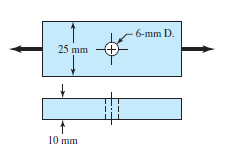

% For AISI 1040 CD
S_ut = 590; % MPa
S_y = 490; % Mpa

F_min = 13.287; % kN
F_max = 31; % kN

w = 25; % mm
d = 6; % mm
t = 10; % mm

% effective cross sectional area at hole
A = (w-d)*t % mm^2

A = 190


dw = d/w

dw = 0.2400


% theoretical stress concentration factor
K_t = 2.45;

% neubers constant for axial loading
neuber_axial = 1.24 ...
               - 2.25*(10^-3)*S_ut ...
               + 1.60*(10^-6)*S_ut^2 ...
               - 4.11*(10^-10)*S_ut^3 % mm^(1/2)

neuber_axial = 0.3850


% notch sensitivity
q = 1/(1 + neuber_axial/sqrt(d/2)) 

q = 0.8181


% fatigue stress concentration factor
K_f = 1 + q*(K_t - 1)

K_f = 2.1863


% Find nominal min and max stress
stress_min_nom = F_min/A * 1000 % MPa

stress_min_nom = 69.9316

stress_max_nom = F_max/A * 1000 % MPa

stress_max_nom = 163.1579


% adjusted min and max stresses
stress_min = K_f * stress_min_nom % MPa

stress_min = 152.8900

stress_max = K_f * stress_max_nom % MPa

stress_max = 356.7089


% Find marin factors

% For surface factor, k_a, part is cold drawn
a_surface = 3.04;
b_surface = -0.217;

k_a = a_surface*S_ut^b_surface

k_a = 0.7614


% For the size factor, specimen is in axial loading
k_b = 1

k_b = 1


% For the loading factor, axial
k_c = 0.85

k_c = 0.8500


% Temperature factor
k_d = 1

k_d = 1


% reliability factor
k_e = 1

k_e = 1


% Find endurance limit
S_e = k_a*k_b*k_c*k_d*k_e*(0.5*S_ut) % MPa

S_e = 190.9148

**Problem 13**

What is the factor of safety against yielding?

stress_max_static = F_max/A * 1000 % Mpa

stress_max_static = 163.1579

n_yield = S_y / stress_max_static

n_yield = 3.0032

**Problem 14**

What are the alternating and mean stresses for this application?

% Factor of safety against yielding
stress_a = (stress_max-stress_min)/2 % MPa

stress_a = 101.9094

stress_m = (stress_max+stress_min)/2 % MPa

stress_m = 254.7994

**Problem 15**

What is the factor of safety against fatigue failure using the Goodman failure criterion, the Gerber failure criterion, and the Morrow criterion?

% Goodman
n_f_goodman = (stress_a/S_e + stress_m/S_ut)^-1

n_f_goodman = 1.0356


% Gerber
n_f_gerber = 0.5 ...
             * (S_ut/stress_m)^2 ...
             * (stress_a/S_e) ...
             * (-1 + sqrt(1 + ((2*stress_m*S_e)/(S_ut*stress_a))^2))

n_f_gerber = 1.2910


% Morrow
stress_f_prime = S_ut + 345;

n_f_morrow = (stress_a/S_e + stress_m/stress_f_prime)^-1

n_f_morrow = 1.2402